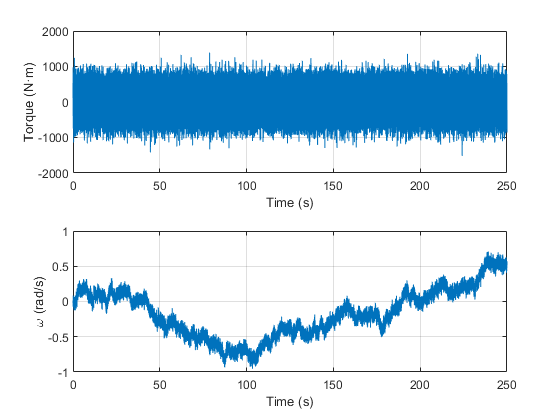

%% Additional tasks
% Дополнительное задание 1
% Идентификация параметров
% Исходные данные: файл, содержащий записи момента и скорости первой 
% массы с периодом дискретизации 1 мс.
% Задания: 
% а) построить частотную характеристику по экспериментальным данным; 
% б) определить параметры двухмассовой механической системы; 
% в) собрать модель с идентифицированными параметрами; 
% г) промоделировать с входным воздействием из исходного файла; 
% д) посчитать среднеквадратичную ошибку между скоростью первой массы с 
% модели и скоростью первой массы из исходного файла.

u = sim_res.out_var.signals.values(:,1);
w1 = sim_res.out_var.signals.values(:,2);
t = sim_res.out_var.time;
%%
figure;
ax1 = subplot(3,1,1);
plot(t, u)
grid on
xlabel("Time (s)"), ylabel("Torque (N·m)")
ax2 = subplot(3,1,2);
plot(t, w1)
grid on
xlabel("Time (s)"), ylabel("\omega (rad/s)")
linkaxes([ax1,ax2],'x')

%%
[txy, f] = tfestimate(u, w1, [], [], [], 1000);
%%
om_1 = 2*pi*f;
L_1=20*log10(abs(txy));
figure();
plot(om_1,L_1)
xlim([0,3000]);
xlabel('\omega_1 (rad/s)')
ylabel('L (dB)')
ax = gca;
set(ax,'Xscale', 'log')
grid on
hold on
%% Подбор параметров модели
Lob = -45.3;
om1 = 56.5;
om2 = 156.5;
Kw = 10^(Lob/20)

Kw = 0.0054

T1 = 1/om1

T1 = 0.0177

T2 = 1/om2

T2 = 0.0064

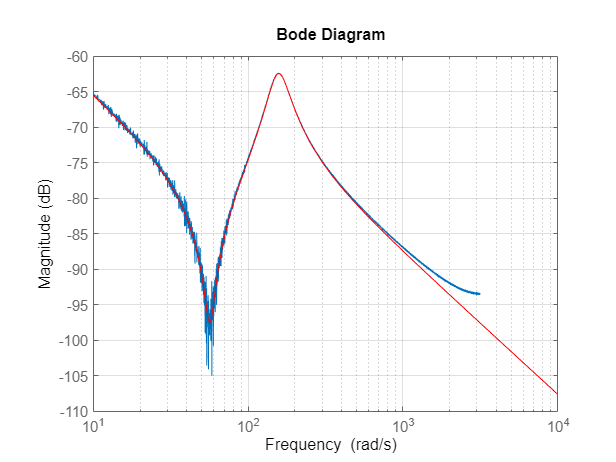

%Попробуем подобрать коэф. демфирования
% ksi1 =0.05;
% ksi2 = 0.05;
ksi1 =0.06;
ksi2 = 0.153;

%%
%Передаточная функция
s = tf('s');
W_ob = Kw*(T1^2*s^2 + 2*T1*ksi1*s +1)/s/(T2^2*s^2 + 2*T2*ksi2*s +1);

bodemag(W_ob,'r')
grid on
hold off

%%
J1=T2^2/(T1^2*Kw)

J1 = 23.9921

J2=1/Kw-J1

J2 = 160.0851

K12=J2/T1^2

K12 = 5.1103e+05

B12=2*ksi2*T2*K12

B12 = 999.2057

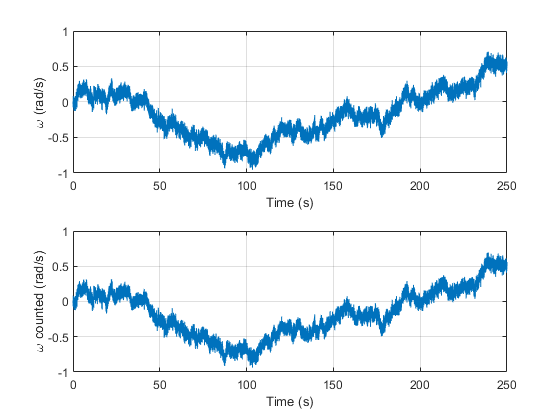

%% E_DriveLab1AddTask modeling
simtime = 250;
res = sim('E_DriveLab1AddTask.slx', simtime);
%%
u_counted = res.out.signals.values(:,1);
w1_counted = res.out.signals.values(:,2);
t_counted = res.out.time;
%%
figure;
ax1 = subplot(2,1,1);
plot(t, w1)
% title("Графики моделирования исходных даных и вычисленной модели")
grid on
xlabel("Time (s)"), ylabel("\omega (rad/s)")
ax2 = subplot(2,1,2);
plot(t_counted, w1_counted)
grid on
xlabel("Time (s)"), ylabel("\omega counted (rad/s)")
linkaxes([ax1,ax2],'x')

%%
e_mse = mse(w1, w1_counted)

e_mse = 9.8317e-05